# **THEORETICAL BSC**

## **Phantom 1**

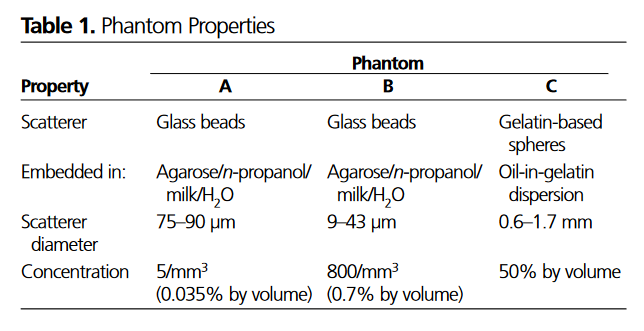

## **Phantom 2-3**

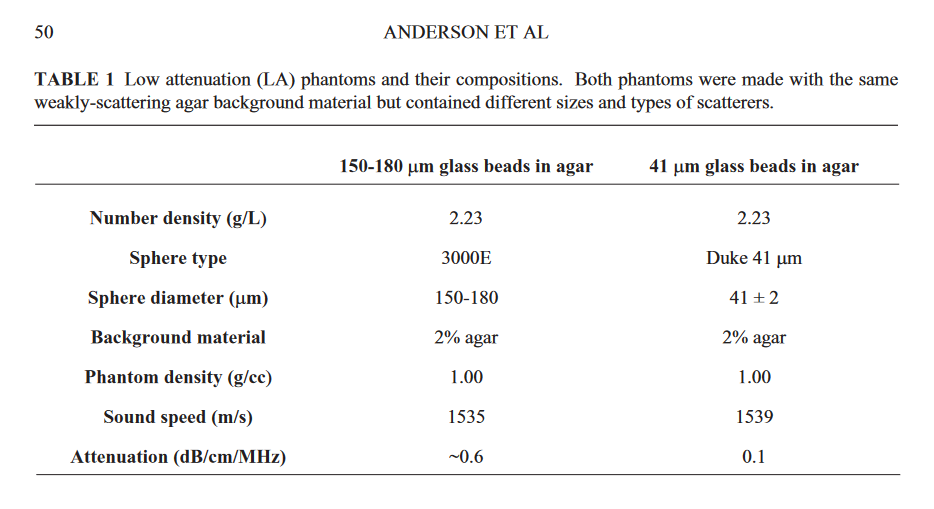


% Phantom 2 and 3
d2 = 41e-6;  % [m] Phantom 2
d3 = 50e-6;  % [m] Phantom 3


vol2 = (4/3)*pi*(d2/2)^3 % [m3]

vol2 = 3.6087e-14

vol3 = (4/3)*pi*(d3/2)^3 % [m3]

vol3 = 6.5450e-14

% volume_mean2 = mean([vol2 vol3]) % [m3]
% volume_mean3 = (4/3)*pi*(mean([d2,d3])/2)^3 % [m3]

% Beads concentration (Interlaboratory Anderson et al.) Number density 2.23g/L
beadsmass_per_ml = 2.23e-6 %g/mm3

beadsmass_per_ml = 2.2300e-06


% Medium density (Interlaboratory Anderson et al.) Phantom density 1g/cc
density = 1e6 % [g/m3]

density = 1000000


% Beads per mm3
% beads_per_mm3 = round(beadsmass_per_ml/(volume_mean2*density))
beads_per_mm3_p2 = round(beadsmass_per_ml/(vol2*density))

beads_per_mm3_p2 = 62

beads_per_mm3_p3 = round(beadsmass_per_ml/(vol3*density))

beads_per_mm3_p3 = 34


% Phantom 1
d1 = 85e-6;  % [m] Phantom 2 (75-90 um)
% vol1 = (4/3)*pi*(d1/2)^3 % [m3]
% beads_per_mm3_p1 = round(beadsmass_per_ml/(vol1*density))
% Beads per mm3
beads_per_mm3_p1 = 5

beads_per_mm3_p1 = 5

## **P2(LA Phantom)** & P3 THERERICAL FARAN THEORY

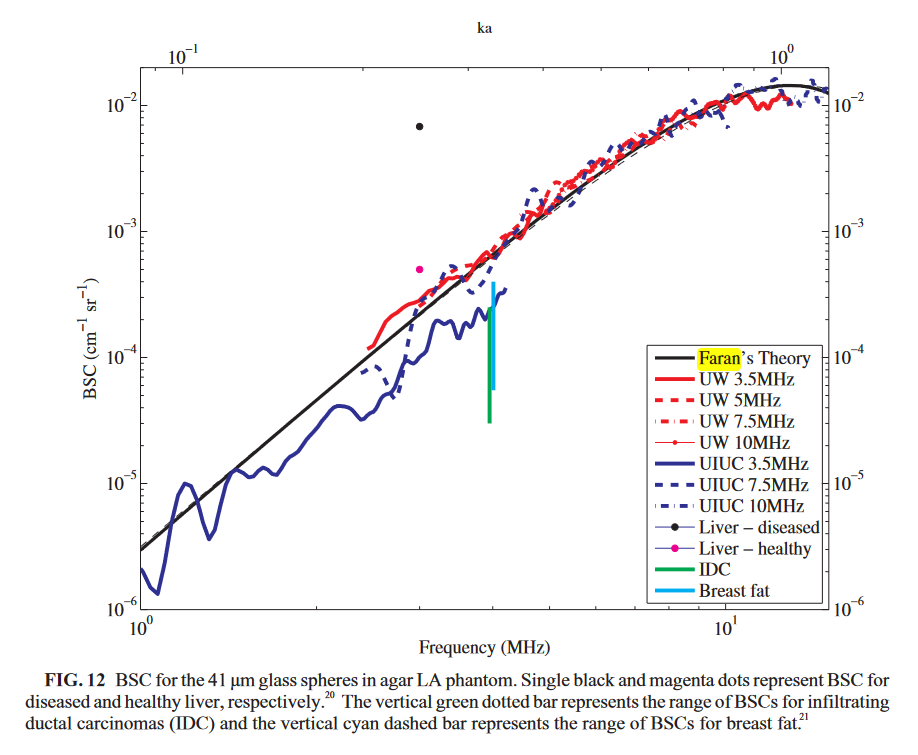

% OFFICAL THEORETICAL
f_min = 1; % [MHz]
f_max = 50; % [MHz]
c0_p1 = 1.54;
c0_p2 = 1.539;
c0_p3 = 1.539;
N_freqs = 100 %50;

N_freqs = 100

anderson_coeffs = load('faran_coeffs.mat', 'anderson_coeffs');

% OLD FUNCTION FIX "d" diamater in [um] of the scatter
% [freq_p2, bsc_p2] = duke_bsc(c0_p2, N_freqs, beads_per_mm3_p2, anderson_coeffs.anderson_coeffs,1,20);
% [freq_p3, bsc_p3] = duke_bsc(c0_p3, N_freqs, beads_per_mm3_p3, anderson_coeffs.anderson_coeffs,1,20);

% NEW FUNCTION TO PASS DIAMETER OF SCATTER in [um]

% Phantom 2
density = 1e6 % [g/m3]

density = 1000000

d2      = 41e-6;  % [m] 
d2_um   = d2*1e6; % [um]
vol2    = (4/3)*pi*(d2/2)^3 % [m3]

vol2 = 3.6087e-14

beadsmass_per_ml = 2.23e-6 % [g/mm3]

beadsmass_per_ml = 2.2300e-06

beads_per_mm3_p2 = round(beadsmass_per_ml/(vol2*density))

beads_per_mm3_p2 = 62


% Phantom 3
d3      = 50e-6;  % [m] Phantom 3
d3_um   = d3*1e6; % [um]
vol3    = (4/3)*pi*(d3/2)^3 % [m3]

vol3 = 6.5450e-14

beadsmass_per_ml = 2.23e-6 % [g/mm3]

beadsmass_per_ml = 2.2300e-06

beads_per_mm3_p3 = round(beadsmass_per_ml/(vol3*density))

beads_per_mm3_p3 = 34


% Phantom 1
d1      = (75:1:90)*1e-6;  % [m] Phantom 3 75-90
d1_um   = d1*1e6; % [um]
beads_per_mm3_p1 = 5 % given by Table 1 + -> + amplitude

beads_per_mm3_p1 = 5

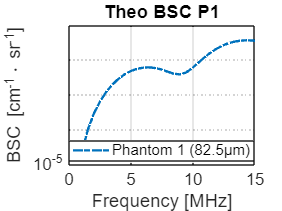

% beads_per_mm3_p1 = 2.5 % given by Table 1

% BSC FARAN THEORY
[freq_p1, bsc_p1] = duke_bsc_a(c0_p1, N_freqs, beads_per_mm3_p1, anderson_coeffs.anderson_coeffs,f_min,f_max,d1_um);
[freq_p2, bsc_p2] = duke_bsc_a(c0_p2, N_freqs, beads_per_mm3_p2, anderson_coeffs.anderson_coeffs,f_min,f_max,d2_um);
[freq_p3, bsc_p3] = duke_bsc_a(c0_p3, N_freqs, beads_per_mm3_p3, anderson_coeffs.anderson_coeffs,f_min,f_max,d3_um);

% For plots
d1_um = mean(d1_um);

% Replicate Phantom 1 results (Theoretical BSC and compare to Paper)
figure,
plot(freq_p1, bsc_p1, '-.', 'LineWidth', 2, 'DisplayName', ['Phantom 1 (', num2str(d1_um),'µm)']); % Use regular plot for loglog axes
hold on;
hold off
grid on;
set(gca, 'YScale', 'log'); % Set Y axis to log
% set(gca, 'XScale', 'log'); % Set X axis to log
xlabel('Frequency [MHz]');
ylabel('BSC [cm^{-1}\cdot sr^{-1}]');
title('Theo BSC P1')
ylim([10^-5, 1*10^-1]);
xlim([0, 15]);
legend('Location', 'best');
set(gca, 'FontSize', 14);

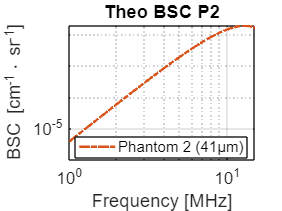


% Replicate Phantom 2 results (Theoretical BSC and compare to Paper)
figure,
plot(freq_p2, bsc_p2, '-.', 'LineWidth', 2, 'Color', [0.8500, 0.3250, 0.0980],'DisplayName', ['Phantom 2 (', num2str(d2_um),'µm)']); % Use regular plot for loglog axes
hold on;
hold off
grid on;
set(gca, 'YScale', 'log'); % Set Y axis to log
set(gca, 'XScale', 'log'); % Set X axis to log
xlabel('Frequency [MHz]');
ylabel('BSC [cm^{-1}\cdot sr^{-1}]');
title('Theo BSC P2')
ylim([10^-6, 2*10^-2]);
xlim([1, 15]);
legend('Location', 'best');
set(gca, 'FontSize', 14);

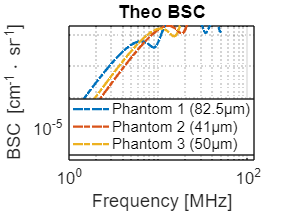



% All Phantoms
figure,
plot(freq_p1, bsc_p1, '-.', 'LineWidth', 2, 'DisplayName', ['Phantom 1 (', num2str(d1_um),'µm)']); % Use regular plot for loglog axes
hold on;
plot(freq_p2, bsc_p2, '-.', 'LineWidth', 2, 'DisplayName', ['Phantom 2 (', num2str(d2_um),'µm)']); % Use regular plot for loglog axes

plot(freq_p3, bsc_p3, '-.','LineWidth', 2, 'DisplayName', ['Phantom 3 (', num2str(d3_um),'µm)']); % Use regular plot for loglog axes
hold off
grid on;
set(gca, 'YScale', 'log'); % Set Y axis to log
set(gca, 'XScale', 'log'); % Set X axis to log
xlabel('Frequency [MHz]');
ylabel('BSC [cm^{-1}\cdot sr^{-1}]');
title('Theo BSC')
ylim([10^-6, 2*10^-2]);
xlim([1, 120]);
legend('Location', 'best');
set(gca, 'FontSize', 14);

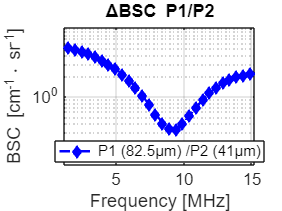



% \Delta BSC
figure, 
plot(freq_p1, bsc_p1./bsc_p2, 'b--', 'Marker', 'diamond', 'MarkerFaceColor','b','LineWidth', 2, 'DisplayName', ['P1 (', num2str(d1_um),'µm) /P2 (', num2str(d2_um),'µm)']); % Use regular plot for loglog axes
hold on;
% plot(freq_p3, bsc_p3, 'LineWidth', 2, 'DisplayName', 'Phantom 3 (50µm)'); % Use regular plot for loglog axes
hold off
grid on;
set(gca, 'YScale', 'log'); % Set Y axis to log
% set(gca, 'XScale', 'log'); % Set X axis to log
xlabel('Frequency [MHz]');
ylabel('BSC [cm^{-1}\cdot sr^{-1}]');
title('\DeltaBSC P1/P2')
ylim([10^-1 10^1]);
xlim([1, 15]);
legend('Location', 'best');
set(gca, 'FontSize', 14);

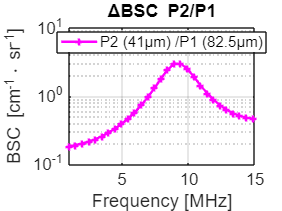


% \Delta BSC
figure, 
plot(freq_p1, bsc_p2./bsc_p1, 'm+-', 'LineWidth', 2, 'DisplayName', ['P2 (', num2str(d2_um),'µm) /P1 (', num2str(d1_um),'µm)']); % Use regular plot for loglog axes
hold on;
% plot(freq_p3, bsc_p3, 'LineWidth', 2, 'DisplayName', 'Phantom 3 (50µm)'); % Use regular plot for loglog axes
hold off
grid on;
set(gca, 'YScale', 'log'); % Set Y axis to log
% set(gca, 'XScale', 'log'); % Set X axis to log
xlabel('Frequency [MHz]');
ylabel('BSC [cm^{-1}\cdot sr^{-1}]');
title('\DeltaBSC P2/P1')
ylim([10^-1 10^1]);
xlim([1, 15]);
legend('Location', 'best');
set(gca, 'FontSize', 14);

## SAVE THEORETICAL BSC

bsc_th = bsc_p1; freq_th = freq_p1;
save('./pythonUIUC/bsc_th_p1.mat', 'bsc_th', 'freq_th');
bsc_th = bsc_p2; freq_th = freq_p2;
save('./pythonUIUC/bsc_th_p2.mat', 'bsc_th', 'freq_th');
bsc_th = bsc_p3; freq_th = freq_p3;
save('./pythonUIUC/bsc_th_p3.mat', 'bsc_th', 'freq_th');


## UNDERSTANDING CHANGES IN bd/mm3, sos and scat-Diam

% TEST CHANGING PARAMETER ONLY TO SEE TENDENCY
% SIZE beads/mm3, fixed 50um diameter
N_freqs = 200 % visualization

N_freqs = 200

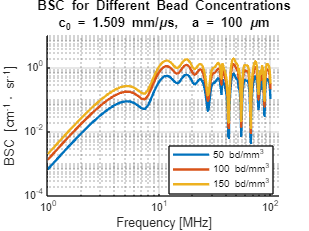

f_min = 1; % [Hz]
f_max = 100; % [Hz]
anderson_coeffs = load('faran_coeffs.mat', 'anderson_coeffs');


% (1) Changing bd/mm3, fix c0 and fix diam_um
beads_per_mm3_array = [50, 100, 150]; % [bd/mm3]
fix_c0              = 1.509; % % [mm/us]
fix_diam_um         = 100; % [um]

figure; hold on;
% set(gcf, 'Position', [10, 10, 500, 400]);
title(['\bfBSC for Different Bead Concentrations', newline, ...
       'c_0 = ' num2str(fix_c0) ' mm/\mus,  a = ' num2str(fix_diam_um) ' \mum']);
legend_labels = strings(1, length(beads_per_mm3_array)); % preallocate legend

for i = 1:length(beads_per_mm3_array)
    [freqs_i, bsc_i] = duke_bsc_a(fix_c0, N_freqs, beads_per_mm3_array(i), ...
        anderson_coeffs.anderson_coeffs, f_min, f_max, fix_diam_um);

    legend_labels(i) = sprintf('%d bd/mm^3', beads_per_mm3_array(i)); % Clear label
    plot(freqs_i, bsc_i, 'LineWidth', 2, 'DisplayName', legend_labels(i)); % Use regular plot for loglog axes
end

set(gca, 'YScale', 'log'); % Set Y axis to log
set(gca, 'XScale', 'log'); % Set X axis to log
% ylim([10^-6, 10^-1.5]);
xlim([1, 120]);
xlabel('Frequency [MHz]');
ylabel('BSC [cm^{-1}\cdot sr^{-1}]');
legend('Location', 'best');
grid on;
hold off;

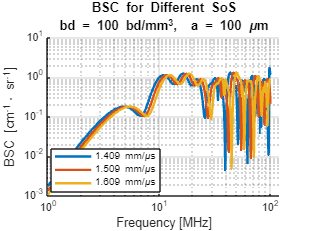


% (2) Changing sos, fix bd/mm3 and fix diam_um
c0_array            = [1.409, 1.509, 1.609]; % [mm/us]
fix_beads_per_mm3   = 100; % [bd/mm3]
fix_diam_um         = 100; % [um]

figure; hold on;
% set(gcf, 'Position', [10, 10, 500, 400]);
title(['\bfBSC for Different SoS', newline, ...
       'bd = ' num2str(fix_beads_per_mm3) ' bd/mm^3,  a = ' num2str(fix_diam_um) ' \mum']);
legend_labels = strings(1, length(c0_array)); % preallocate legend

for i = 1:length(c0_array)
    [freqs_i, bsc_i] = duke_bsc_a(c0_array(i), N_freqs, fix_beads_per_mm3, ...
        anderson_coeffs.anderson_coeffs, f_min, f_max, fix_diam_um);

    legend_labels(i) = sprintf('%.3f mm/\\mus', c0_array(i)); % Clear label
    plot(freqs_i, bsc_i, 'LineWidth', 2, 'DisplayName', legend_labels(i)); % Use regular plot for loglog axes
end

set(gca, 'YScale', 'log'); % Set Y axis to log
set(gca, 'XScale', 'log'); % Set X axis to log
% ylim([10^-6, 10^-1.5]);
xlim([1, 120]);
xlabel('Frequency [MHz]');
ylabel('BSC [cm^{-1}\cdot sr^{-1}]');
legend('Location', 'best');
grid on;
hold off;

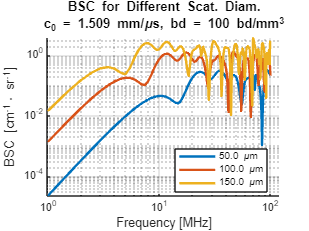


% (3) Changing diam_um, fix c0 and fix bd/mm3
diam_um_array       = [50 100 150]; % [um]
fix_c0              = 1.509; % [mm/us]
fix_beads_per_mm3   = 100; % [bd/mm3]


figure; hold on;
% set(gcf, 'Position', [10, 10, 500, 400]);
title(['\bfBSC for Different Scat. Diam.', newline, ...
       'c_0 = ' num2str(fix_c0) ' mm/\mus, ', 'bd = ' num2str(fix_beads_per_mm3) ' bd/mm^3']);
legend_labels = strings(1, length(diam_um_array)); % preallocate legend

for i = 1:length(diam_um_array)
    [freqs_i, bsc_i] = duke_bsc_a(fix_c0, N_freqs, fix_beads_per_mm3, ...
        anderson_coeffs.anderson_coeffs, f_min, f_max, diam_um_array(i));

    legend_labels(i) = sprintf('%.1f \\mum', diam_um_array(i)); % Clear label
    plot(freqs_i, bsc_i, 'LineWidth', 2, 'DisplayName', legend_labels(i)); % Use regular plot for loglog axes
end

set(gca, 'YScale', 'log'); % Set Y axis to log
set(gca, 'XScale', 'log'); % Set X axis to log
% ylim([10^-6, 10^-1.5]);
xlim([1, 120]);
xlabel('Frequency [MHz]');
ylabel('BSC [cm^{-1}\cdot sr^{-1}]');
legend('Location', 'best');
grid on;
hold off;

function [freqs, bsc] = duke_bsc(c0, N_freqs, beads_per_mm3, anderson_coeffs, low_freq, high_freq)

    freqs = linspace(low_freq, high_freq, N_freqs);   freqs = freqs(:);
    k0s = 2*pi*freqs/c0;
    
    % The scatterer radii in mm:
    a_values = (38:1:45)/2000; %um a mm, r -> d
    % The radii pdf:
    n_values = ones(size(a_values));
    n_values = n_values/sum(n_values);
    N_vals = length(a_values);
    
    bsc = zeros(N_freqs, 1);
    
    for index = 1:N_vals
        bsc = bsc + n_values(index)*pi*(a_values(index))^2*ppval(anderson_coeffs, k0s*a_values(index));
    end
    
    scats_per_mm3 = beads_per_mm3/4/pi;
    bsc = scats_per_mm3*bsc;
    
    % Finally, converting to cm^-1:
    bsc = 10*bsc;
end

function [freqs, bsc] = duke_bsc_band(c0, band, beads_per_mm3, anderson_coeffs)

    freqs = band;
    k0s = 2*pi*freqs/c0;
    
    % The scatterer radii in mm:
    a_values = (38:1:45)/2000; %um a mm, r -> d
    % The radii pdf:
    n_values = ones(size(a_values));
    n_values = n_values/sum(n_values);
    N_vals = length(a_values);
    
    bsc = zeros(length(band), 1);
    
    for index = 1:N_vals
        bsc = bsc + n_values(index)*pi*(a_values(index))^2*ppval(anderson_coeffs, k0s*a_values(index));
    end
    
    scats_per_mm3 = beads_per_mm3/4/pi;
    bsc = scats_per_mm3*bsc;
    
    % Finally, converting to cm^-1:
    bsc = 10*bsc;
end

function [freqs, bsc] = duke_bsc_a(c0, N_freqs, beads_per_mm3, anderson_coeffs, low_freq, high_freq, diam_um)

    freqs = linspace(low_freq, high_freq, N_freqs);   freqs = freqs(:);
    k0s = 2*pi*freqs/c0;
    
    % The scatterer radii in mm:
    % a_values = (38:1:45)/2000; %um a mm, 
    a_values = (diam_um/2)*1e-3; %um a mm, (diameter to radious)
    % The radii pdf:
    n_values = ones(size(a_values));
    n_values = n_values/sum(n_values);
    N_vals = length(a_values);
    
    bsc = zeros(N_freqs, 1);
    
    for index = 1:N_vals
        bsc = bsc + n_values(index)*pi*(a_values(index))^2*ppval(anderson_coeffs, k0s*a_values(index));
    end
    
    scats_per_mm3 = beads_per_mm3/4/pi;
    bsc = scats_per_mm3*bsc;
    
    % Finally, converting to cm^-1:
    bsc = 10*bsc;
end

